# Sistemas de servoposición

Estes es un sistema de control muy común, se busca controlar tanto la posición como la velocidad de giro del motor.

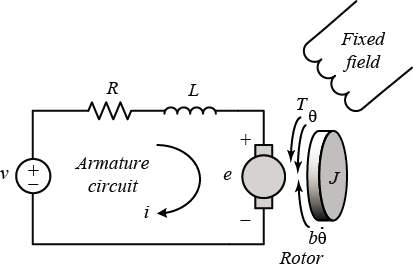

El modelo de Kirchoff para voltajes


$$v=R\;i+L\frac{\mathrm{d}}{\textrm{dt}}i+e_m$$


Donde $e_m$ es la fuerza electromotriz. El modelo de segunda Ley de Newton, para un sistema de partículas, considerando el brazo de palanca. Este modelo es la segunda ley de Newton rotacional.


$$\;\sum_i m_{i\;} \;r_{i\;} \times \;a_{i\;} =\sum_i r_{i\;} \times F_{i\;}$$


Pero cuando la aceleración se debe unicamente al giro respecto a un eje, es decir, la aceleración angular $\alpha \;$. 


$$a_{i\;} =\alpha \;\times r_{i\;}$$


Sustituyendo en la segunda ley de Newton rotacional


$$\sum_i m_{i\;} \;r_{i\;} \times \alpha \;\times r_{i\;} =\sum_i m_{i\;} \;\left(r_{i\;} \cdot r_{i\;} I-r_i \otimes r_i \right)\cdot \alpha \;\;=\sum_i r_{i\;} \times F_{i\;}$$


Donde $\left(r_{i\;} \cdot r_{i\;} -r_i \otimes r_i \right)$ es el tensor de inercia $J$ y $r_{i\;} \times F_{i\;} =T_{i\;}$ son lo momentos aplicados al cuerpo.

 
$$J\;\alpha =J\frac{{\mathrm{d}}^2 }{{\textrm{dt}}^2 }\theta =\sum T_{i\;} =-b\;\frac{\mathrm{d}}{\mathrm{d}\mathrm{t}}\theta +T_e \;$$


Se tienen que combinar la segunda ley de Newton con la ley Kirchoff de voltajes, para ello se utiliza el modelo del motor. el torque elécrico $T_e$ depende del la corriente que pasa por el motor, mientras que la fuerza electromotriz $e_m$ depende de la velocidad angular.


$$T_e =k\;i;\;\;\;\;\;\;\;\;e_m =k$$

$$\frac{d}{\mathrm{d}t}\theta$$


Donde $k$, es la constante del motor. Utilizando este modelo en las ecuaciones anteriores se obtiene el modelo del sevomotor


$$v=R\;i+L\frac{\mathrm{d}}{\textrm{dt}}i+k\;\frac{\mathrm{d}}{\mathrm{d}t}\theta ;$$
                
$$J\;\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\theta =-b\;\frac{\mathrm{d}}{\mathrm{d}t}\theta +k\;i$$


De ambas ecuaciones se busca eliminar la corriente del modelo. $v=f\left(\theta \;,\frac{\mathrm{d}}{\mathrm{d}t}\theta \;\right)$. Utilizando transformada de Laplace.

$V\left(s\right)=$$R\;I\left(s\right)+L\;s\;I\left(s\right)+k\;s\;\Theta \;\left(s\right)$;        $J\;s^{2\;} \Theta \left(s\right)\;=-b\;s\;\Theta \left(s\right)+k\;I\left(s\right)$

$\frac{V\left(s\right)-k\;s\;\Theta \;\left(s\right)}{\left(R+L\;s\right)}=$$\;I\left(s\right)$;            $\;s^{\;} \left(J\;s+b\right)\Theta \left(s\right)\;=k\;I\left(s\right)$

$\;\Theta \;\left(s\right)=\frac{k}{\left(s+0\right)\left(\left(J\;s+b\right)\left(R+L\;s\right){+k}^2 \;\right)}\;V\left(s\right)$        Este es el modelo del servo motor para posición angular

$\;\Omega \;\left(s\right)=\frac{k}{\left(\left(J\;s+b\right)\left(R+L\;s\right){+k}^2 \;\right)}\;V\left(s\right)$                  Este es el modelo de servo motor para velocidad angular


clc;
clear all;
close all;

J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
R = 4;
L = 2.75E-6;
s = tf('s');

P_motor = K/((J*s+b)*(L*s+R)+K^2);
P_motor = P_motor/s

P_motor =
 
                    0.0274
  -------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s
 
Continuous-time transfer function.




% for i = 1:3
%     P_motor(:,:,i) = K/((i*J*s+b)*(L*s+R)+K^2);
% %     [num den] = tfdata(P_motor, 'v')
%     
% end 

t = 0:0.001:0.2;
figure(1);
subplot(1,2,1);     step(P_motor);      xlabel('Tiempo, [s]');    ylabel('Posición, \theta [rad]');
subplot(1,2,2);     pzmap(P_motor)

La respuesta se obtenida se obtiene debido a que la respuesta a un escalon, cuando se tiene un integrador $\frac{1}{s}$


$$\Theta \;\left(s\right)=\frac{1}{s}\left(\frac{k}{\left(J\;s+b\right)\left(R+L\;s\right){+k}^2 }\right)\;\;V\left(s\right)$$


## Retroalimentación

Con la función `feedback(Planta, Controlador) `se define un lazo cerrado de control

sys_cl = feedback(P_motor,1)

sys_cl =
 
                         0.0274
  ----------------------------------------------------
  8.878e-12 s^3 + 1.291e-05 s^2 + 0.0007648 s + 0.0274
 
Continuous-time transfer function.




figure(2)
step(sys_cl);   xlabel('Tiempo, [s]');    ylabel('Posición, \theta [rad]');

Como se puede observar el sistema llega a la energía total suministrada, esto tambien se debe al integrador $\frac{1}{s}$

[Wn,zeta,poles] = damp(sys_cl);
Mp = exp((-zeta(1)*pi)/sqrt(1-zeta(1)^2))

Mp = 0.0716

Ts = 5/(zeta(1)*Wn(1))

Ts = 0.1688

Los valores obtenidos se definene para el sobrepaso $M_p$ y el tiempo de asentamiento $t_s$, el cual define el tiempo que le toma al sistema en estabilizarse.

## Control P

En el siguiente ejemplo se muestra un control P, aplicado en el servomotor, con valores $K_{p\;} =\left\lbrace 1,11,21\right\rbrace$

Kp = 1;
for i = 1:3
    C(:,:,i) = pid(Kp);
    Kp = Kp + 10;
end
t = 0:0.001:0.2;

figure(3);
sys_cl = feedback(C*P_motor,1);
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t);
xlabel('Tiempo, [s]');    ylabel('Posición, \theta [rad]');
title('Respuesta al escalón como referencia con distintos valores de K_p')
legend('Kp = 1',  'Kp = 11',  'Kp = 21')

De acuerdo a lo observado en control PID de las sesiones anteriores, se puede observar que al aumentar el control P, el sistema se vuelve subamortiguado, además, que la frecuencia natural aumenta.

## Control PI

A continuación se observan los efectos de un controlodor PI, se deja fijo el valor de $K_{p\;}$ y se varia $K_I$


Kp = 21;
Ki = 100;
for i = 1:5
    C(:,:,i) = pid(Kp,Ki);
    Ki = Ki + 200;
end

sys_cl = feedback(C*P_motor,1);
t = 0:0.001:0.4;

step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Respuesta a un escalón como referencia con K_p = 21 y distintos valores de K_i')
legend('Ki = 100', 'Ki = 300', 'Ki = 500')

## PID

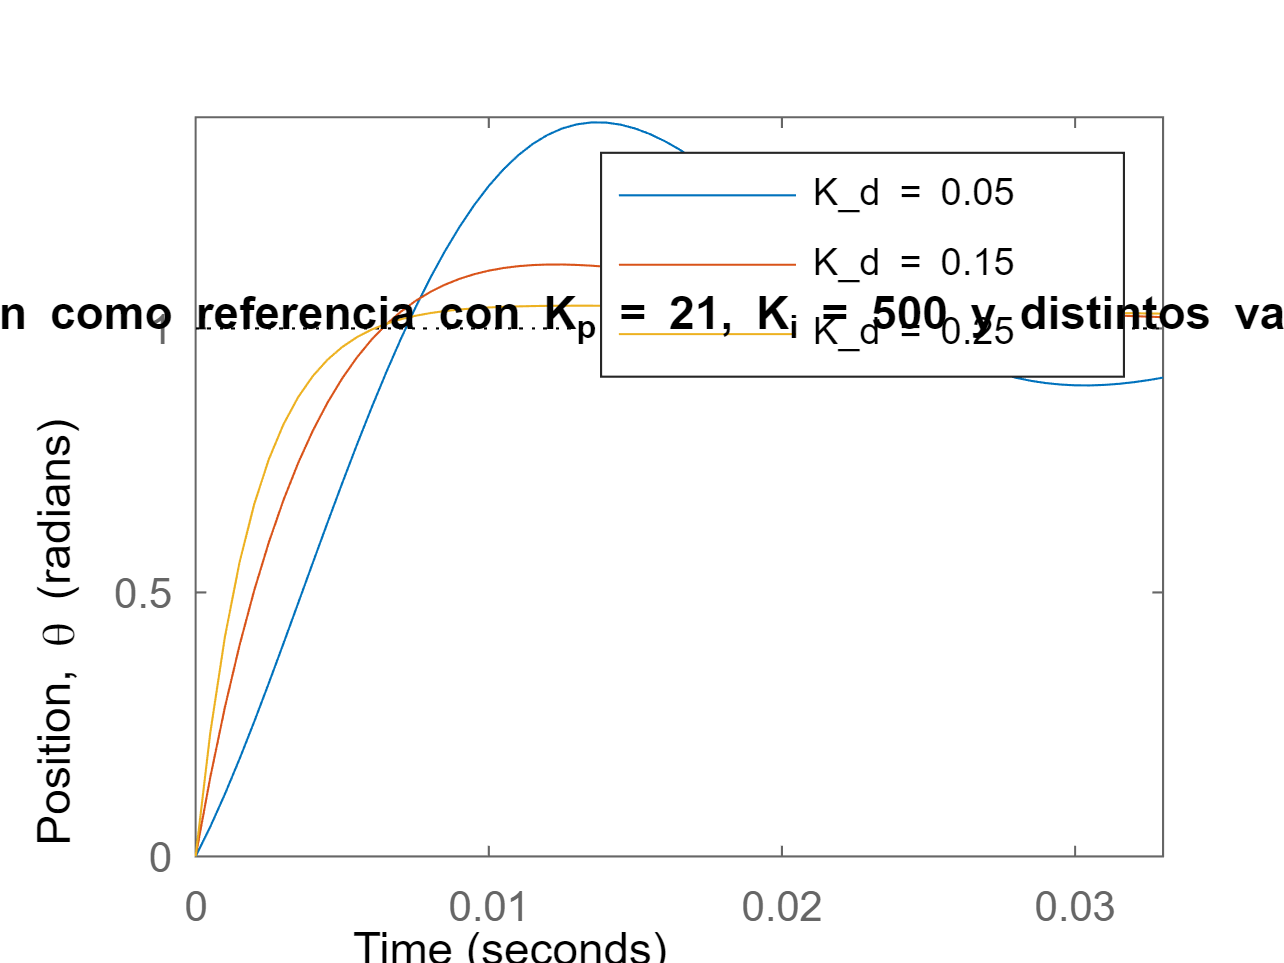

kp = 21;
ki = 500;
kd = [0.05   0.15   0.25];

for i = 1:3
    C(:,:,i) = pid(kp , ki, kd(i));
    sys_cl = feedback(C*P_motor,1);
end

t = 0:0.0005:0.033;
step(sys_cl(:,:,1), sys_cl(:,:,2), sys_cl(:,:,3), t)
ylabel('Position, \theta (radians)')
title('Respuesta a un escalón como referencia con K_p = 21, K_i = 500 y distintos valores de K_d')
legend('K_d = 0.05', 'K_d = 0.15', 'K_d = 0.25')

clc;
close all;

info = stepinfo(sys_cl(:,:,2))

info = struct with fields:
         RiseTime: 0.0046
    TransientTime: 0.0338
     SettlingTime: 0.0338
      SettlingMin: 0.9103
      SettlingMax: 1.1212
        Overshoot: 12.1175
       Undershoot: 0
             Peak: 1.1212
         PeakTime: 0.0122


Ts = info.SettlingTime;
T = Ts

T = 0.0338


for i = 1:4
    T = (T/2);
    sys_d{i} = c2d(sys_cl(:,:,2), T, 'zoh'); 
end

figure(4);
step(sys_cl(:,:,2), sys_d{1}, sys_d{2}, sys_d{3}, sys_d{4}, 1.5*Ts);  
legend('Continuo', 'T = Ts/2', 'T = Ts/4', 'T = Ts/8', 'T = Ts/16');



% stepinfo(sys_cl(:,:,2))

### Espacio de Estados

Cuando se requiere controlar varios elementos al mismo tiempo, es decir, sistemas Múltiple Entrada Múltiple Salida (MIMO, por sus siglas en inglés), se puede utilizar otra representación de las ecuaciones dinámicas del sistema, como son la ecuaciones de espacio estado (SS por sus siglas en inglés)


$$v=R\;i+L\;\dot{i} +k\;\dot{\theta} ;$$
                
$$J\ddot{\theta} =-b\;\dot{\theta} +k\;i$$


si $\dot{\theta \;} =\omega \;$

Reescrito como en forma matricial


$$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
\omega \;\\
i
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{k}{J}\\
-\frac{k}{L} & -\frac{R}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega \;\\
i
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{L}
\end{array}\right\rbrack v$$


Suponiendo que solo queremos ver como salida la velocidad angular $\omega$

clc;
clear all;

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
A = [-b/J   K/J
    -K/L   -R/L];
B = [0
    1/L];
C = [1   1];
D = 0;
sys = ss(A,B,C,D);

Obtención de polos

poles = eig(A)

poles =    -9.9975
   -2.0025
